# Notes regarding lab format

We will use Matlab Livescript for this lab. Livescript allows switching between text and code cells. 

You will find the entire lab manual in this file. Some exercises require you to write a text answer, others require you to write code. You should not define functions inside this file. Instead save functions to the functions folder and call them from the code cells in this notebook.

Your finished lab report should be a .zip-file containing the data folder, your functions folder, any output images you might have saved and this livescript file.

Since we need to access the functions and data folder the first step is to add these two locations to MATLAB's path.

addpath('./functions');

addpath('./data');

**Important rules:** You are only allowed to ask TAs and lectures for help. It is not allowed to copy solutions, not even partially, from other sources (your fellow students, internet, Large Language Models or whatever).

# Lab 2: Learning and convolutional neural networks

## 2.1 Learning a Linear Classifier

In this part, we will try to learn a linear classifier for blood cell detection. Note that the classifier could also be viewed as a minimal neural network consisting of three parts: a scalar product node (or fully-connected node), a constant (or bias) term and a logistic sigmoid function. To find good parameters we will try to minimize the negative log-likelihood over a small training set.

The output from our classifier is a probability p for the input patch being centered at a cell centre. The sigmoid function will make sure that 0 ≤ p ≤ 1. To be more precise the output is


$$p=\frac{e^y }{1+e^y }\;\;\;\;\textrm{where}\;\;\;\;y=I\cdot \omega +\omega_0$$


Instead of testing a bunch of manually chosen w’s and w_0’s, we will try to learn good values for all the parameters. This requires training examples, that you find in cell_data.mat.

## Ex 2.1 

## Load the data using

load cell_data.mat

It loads a structure, cell_data, with two fields, `fg_patches` and `bg_patches`, corresponding to positive (centered blood cells) negative examples respectively.

## Ex 2.2 

Create two new variables, examples and labels. The variable examples should be a cell structure containing all the patches (both positives and negatives) and labels should be an array with the same number of elements such that `labels(i) = 1` if` examples{i}` is a positive example, and `labels(i) = 0` otherwise.

% Your code here
% Combine positive and negative patches into one cell array
data = [cell_data.fg_patches, cell_data.bg_patches];
labels = [zeros(1, size(cell_data.fg_patches,2)), ones(1, size(cell_data.bg_patches,2))];

## Ex 2.3

Split the data into training,` (examples_train, labels_train)`, and validation,` (examples_val, labels_val)`. The two should have a similar structure to examples and labels. Write on the report which percentage of the data you used for validation. Also, the splitting of the data into the two sets should be done in a random manner, for example, using randperm. 

**Percentage of data used for training**: 80%

**Percentage of data used for validation**: 20%

% Your code here
percentage_validation = 0.8;
N = size(data,2);

train_size = round(N*percentage_validation);
val_size = N - train_size;

indexes = randperm(N);

data_train = data(indexes(1:train_size));
labels_train = labels(indexes(1:train_size));

data_val = data(indexes(train_size+1:end));
labels_val = labels(indexes(train_size+1:end));

## 2.2 Training the classifier

We will try to find parameters that minimize the negative log-likelihood on the training data. More precisely,


$$L\left(\theta \right)=\sum_{i\in S_+ } -\ln \left(p_i \right)+\sum_{i\in S_- } -\ln \left(1-p_i \right)=\sum_i L_i \left(\theta \right)$$


where $p_i$ refers to the classifier output for the ith training example. As in the lectures we will refer to the terms here as the partial loss $L_i$.

Before doing the next exercise, you need to work out how to compute the gradient of the partial loss $L_i$.

## Ex 2.4

Make a function

        `[wgrad, w0grad] = partial_gradient(w, w0, example_train, label_train)`

that computes the derivatives of the partial loss L_i with respect to each of the classifier parameters. Let the output wgrad be an array of the same size as the weight image, w (and let w0grad be a number). 

At each iteration of stochastic gradient descent, a training example, i, is chosen at random. For this example the gradient of the partial loss, L_i , is computed and the parameters are updated according to this gradient. The most common way to introduce the randomness is to make a random reordering of the data and then going through it in the new order. One pass through the data is called an epoch.

## Ex 2.5

Make a function

        `[w, w0] = process_epoch(w, w0, lrate, examples_train, labels_train)`

that performs one epoch of stochastic gradient descent

## Ex 2.6 

Initialize `w = s * randn(35,35);`, with `s = 0.01` and `w0 = 0;` and run 5 epochs on your training examples. Plot w after each epoch (or after each iteration if you are curious), to get a sense of what is happening. Also, try using different `s={10,1,0.1,0.01}` and plot w after 5 epochs for each value of s. Include on the report visualizations of w for the different values of s, along with an written explanation of what is happening.

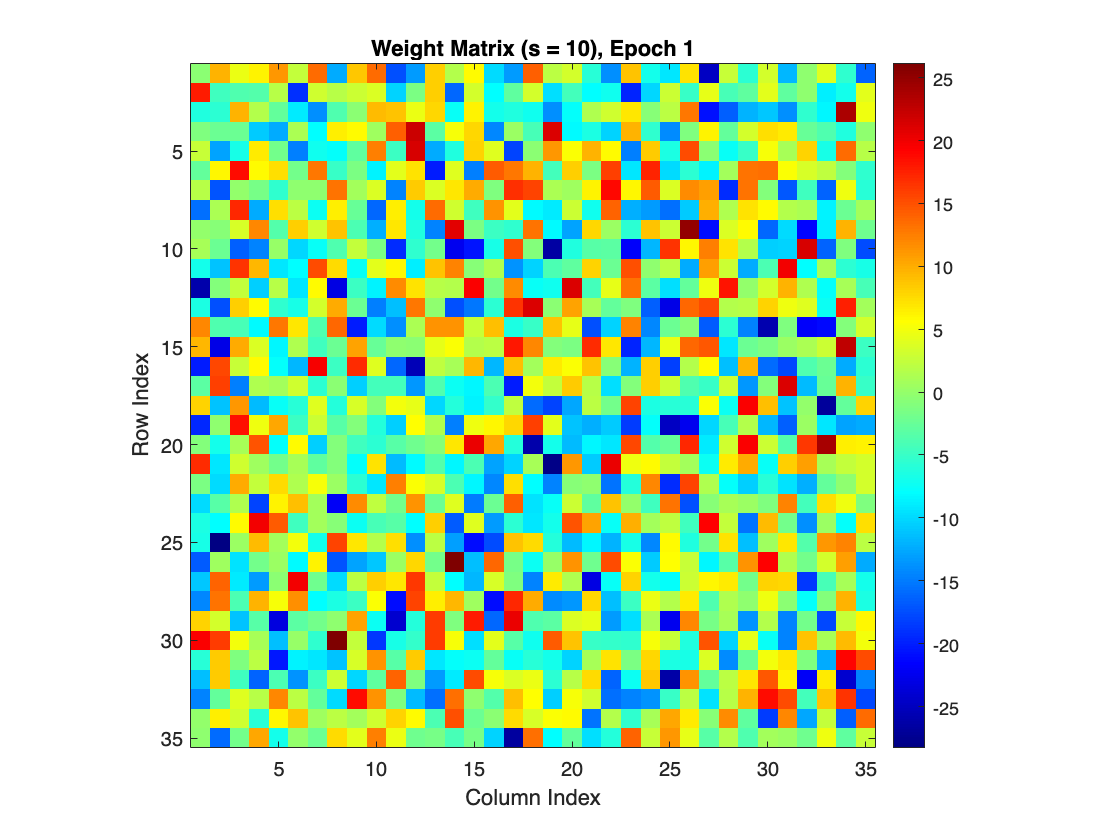

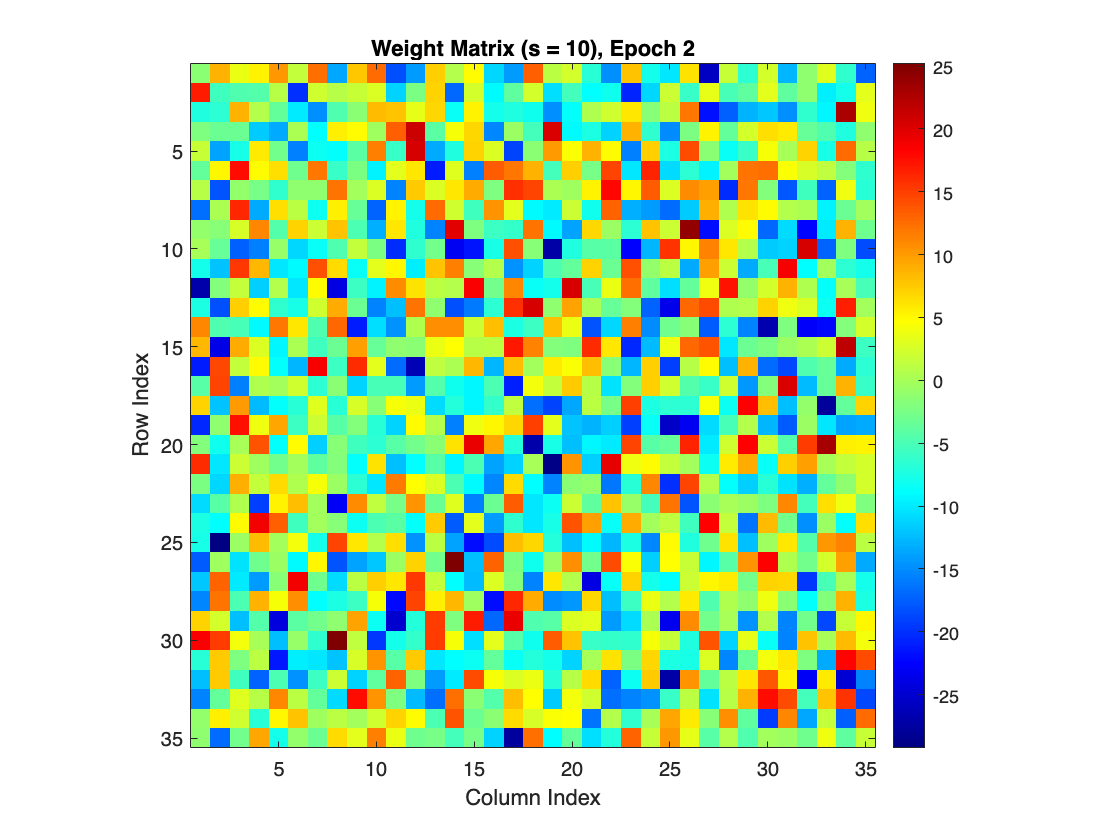

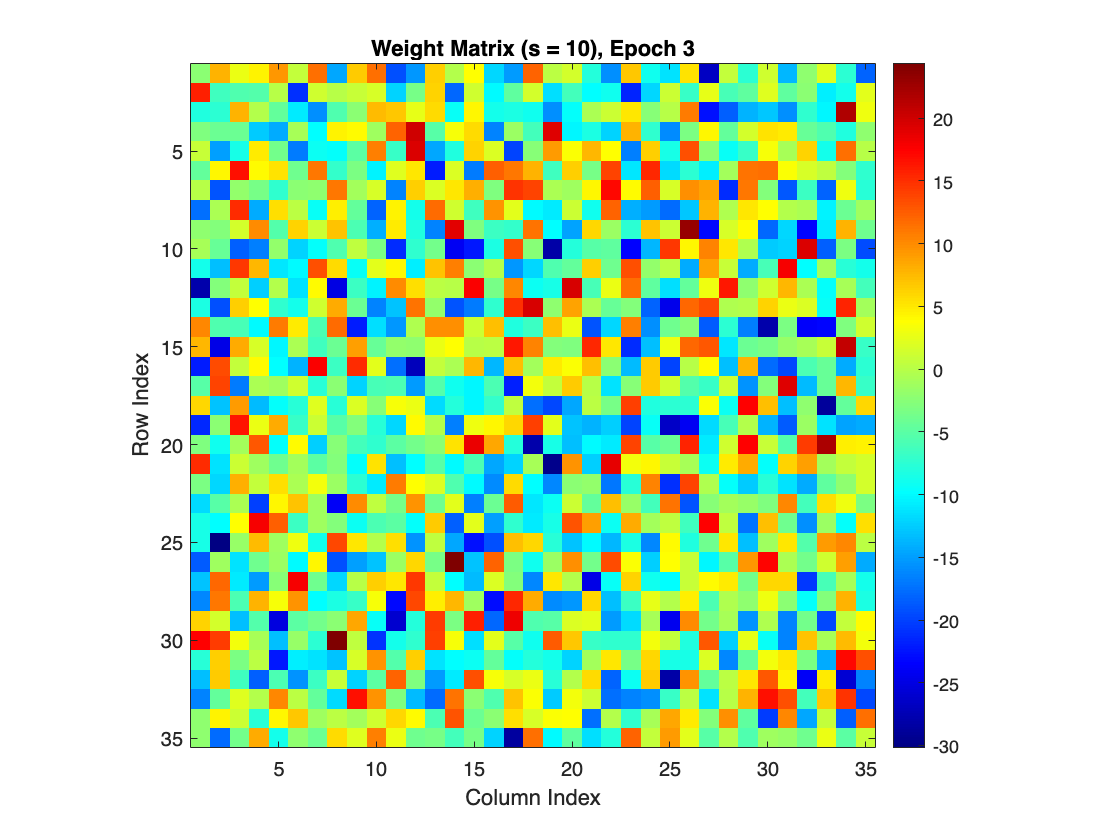

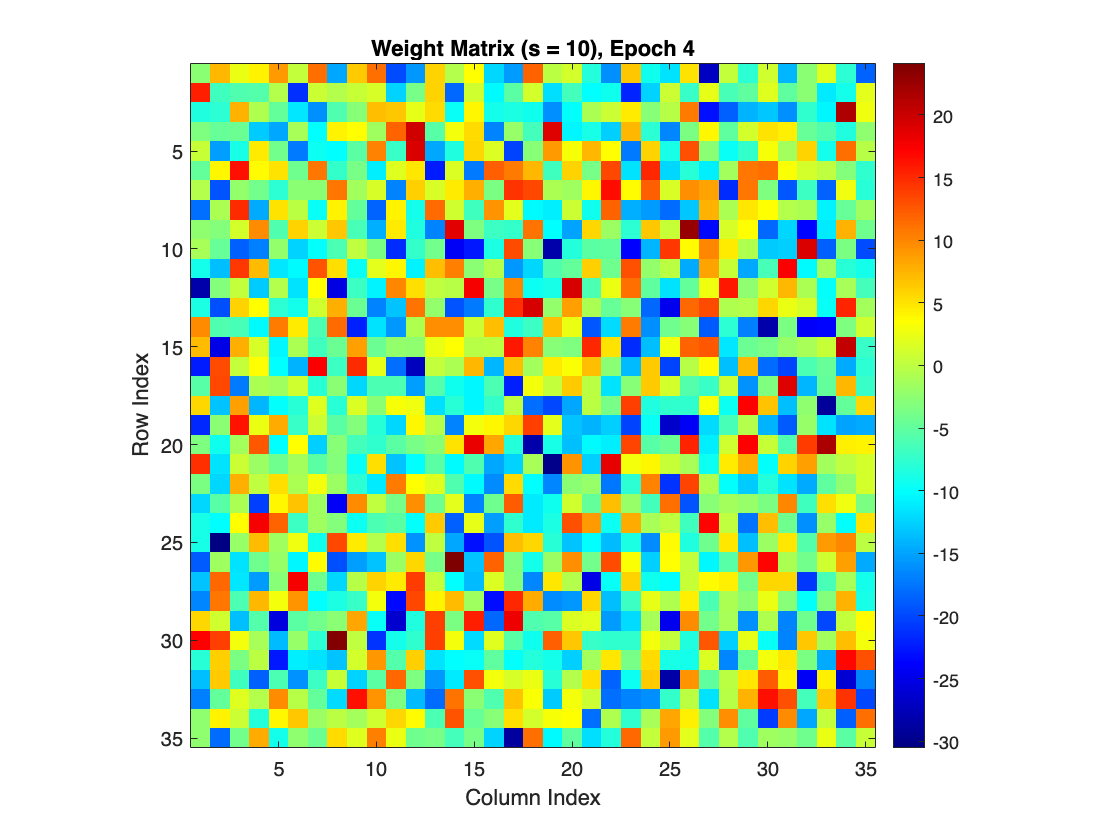

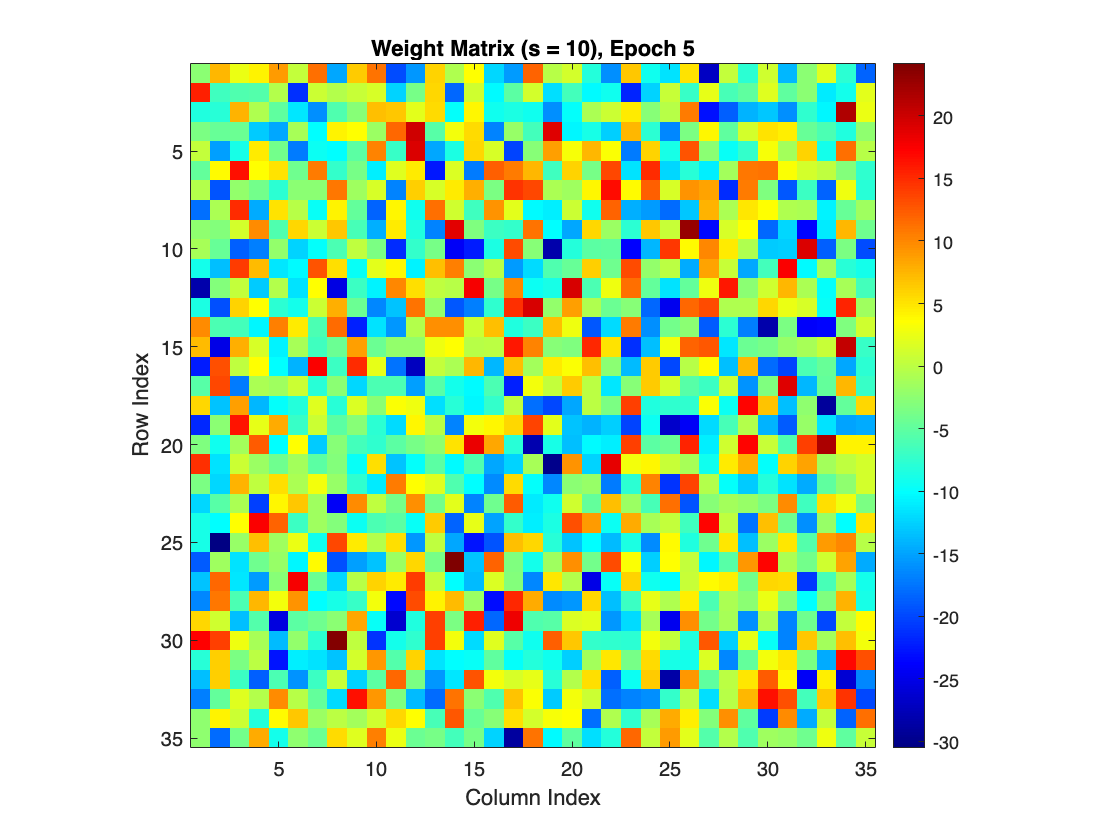

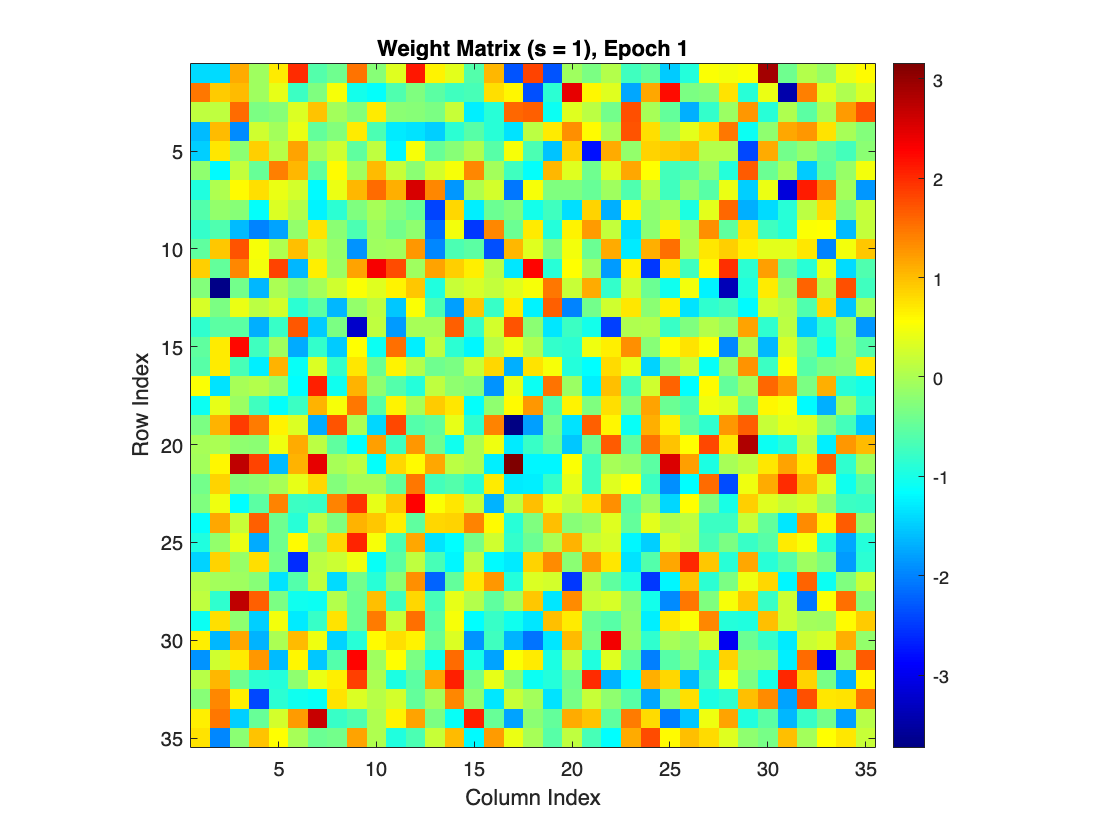

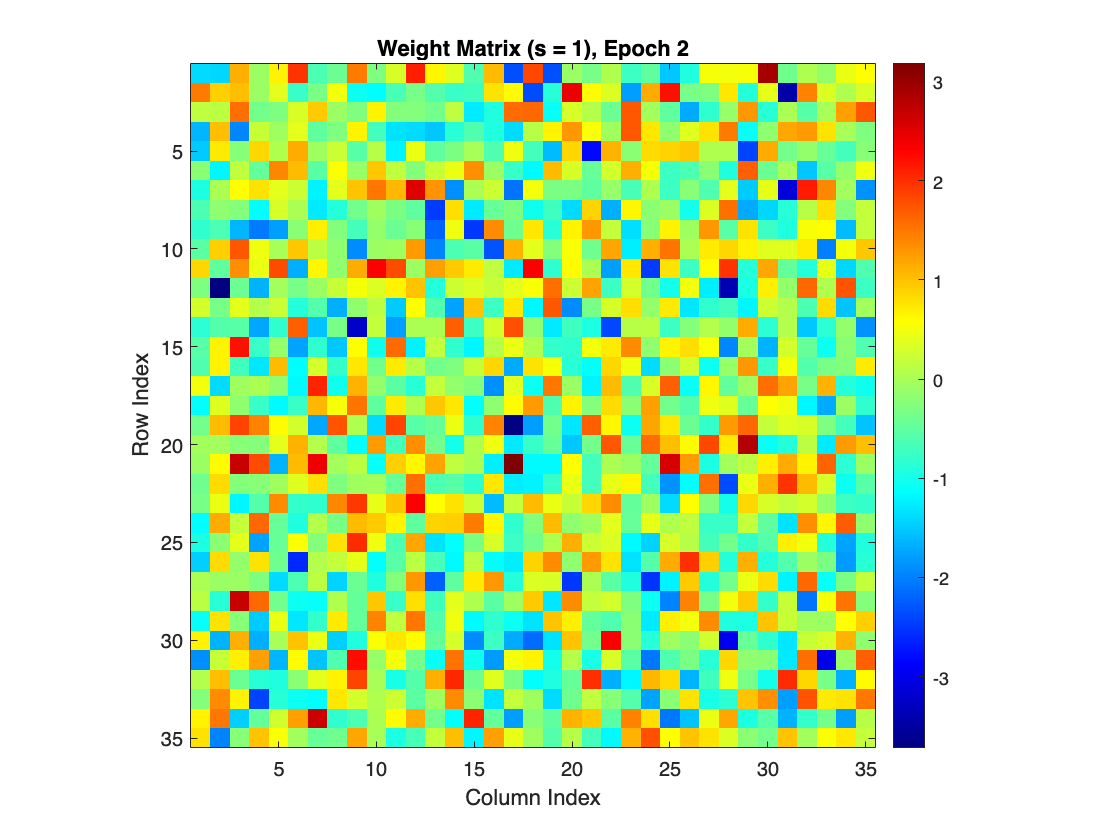

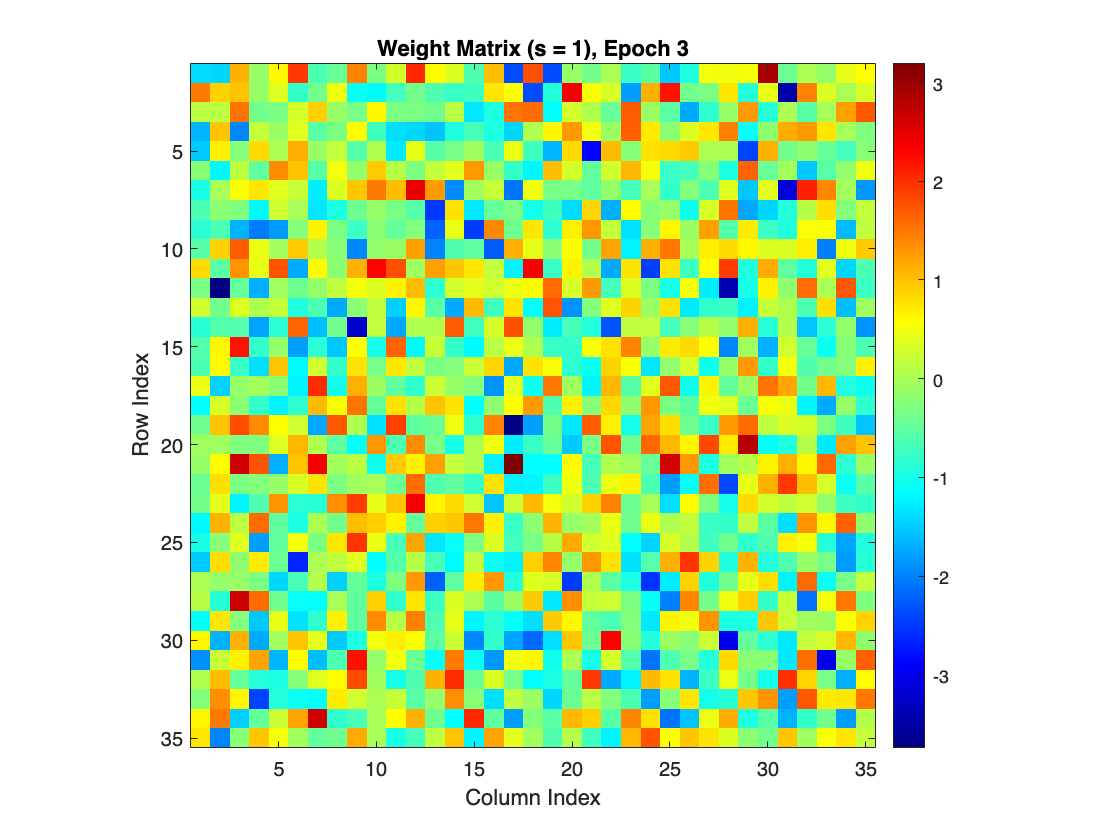

% your code here
% Initialize parameters
s_values = [10, 1, 0.1, 0.01];
num_epochs = 5;

% Load data and initialize w0
load cell_data.mat
w0 = 0;

% Perform SGD with different s values
for s = s_values
    % Initialize w
    w = s * randn(35, 35);

    % Perform epochs
    for epoch = 1:num_epochs
        % Process one epoch of SGD
        [w, w0] = process_epoch(w, w0, 0.01, data_train, labels_train);

        % Plot w after each epoch
        figure;
        imagesc(w);
        colorbar;
        title(['Weight Matrix (s = ' num2str(s) '), Epoch ' num2str(epoch)]);
        xlabel('Column Index');
        ylabel('Row Index');
        axis square;
        colormap('jet');
        drawnow;
    end
end

**Your written answer here:**

Initially, we observe the gradient evolving across epochs, suggesting its active updating. Examining the initialization of the weight matrix, a random procedure, reveals its impact on the classifier's learning process. Modifying the initial weight matrix by a scalar, denoted as 's', directly influences training. As noted earlier, training, characterized by stochastic descent, relies on the gradient and subsequent weight matrix adjustments.

## Exercise 2.7

As said before, at each iteration of stochastic gradient descent, a training example is chosen at random. Check what happens to w after 5 epochs when that training example is not chosen randomly but in sequence, i.e. first `i = 1`, then `i = 2`, and so on. Include on the report a visualization of w for this case. (Don’t forget to change back your function to a random choice of i after this exercise).

You can display the resulting filters inside this livescript notebook using the function imagesc.

S: 10


Epoch: 0


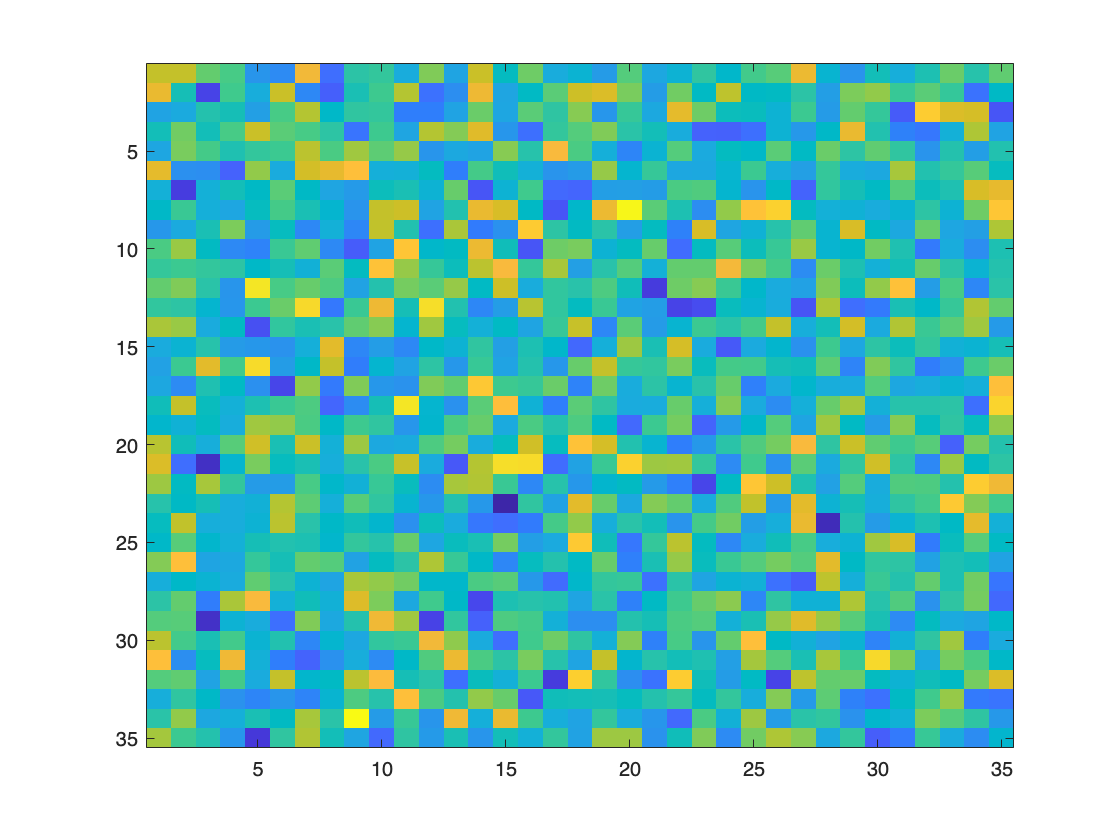

Epoch 5


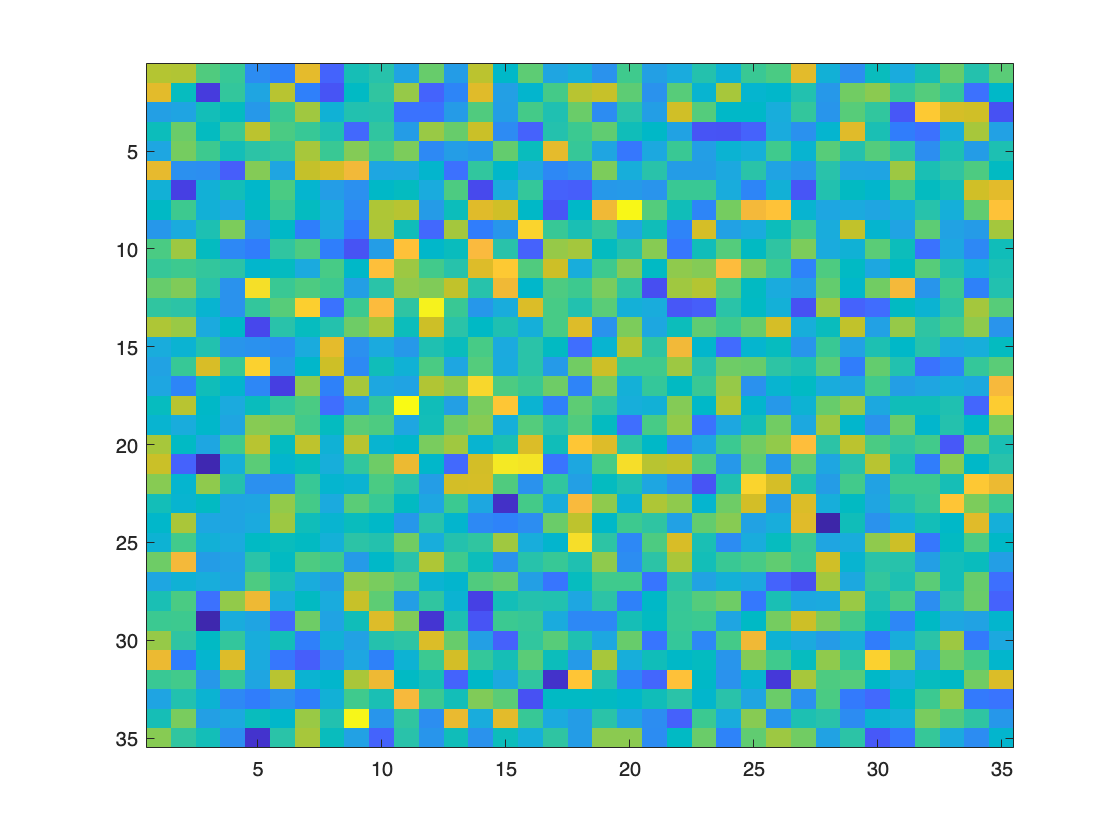

S: 1


Epoch: 0


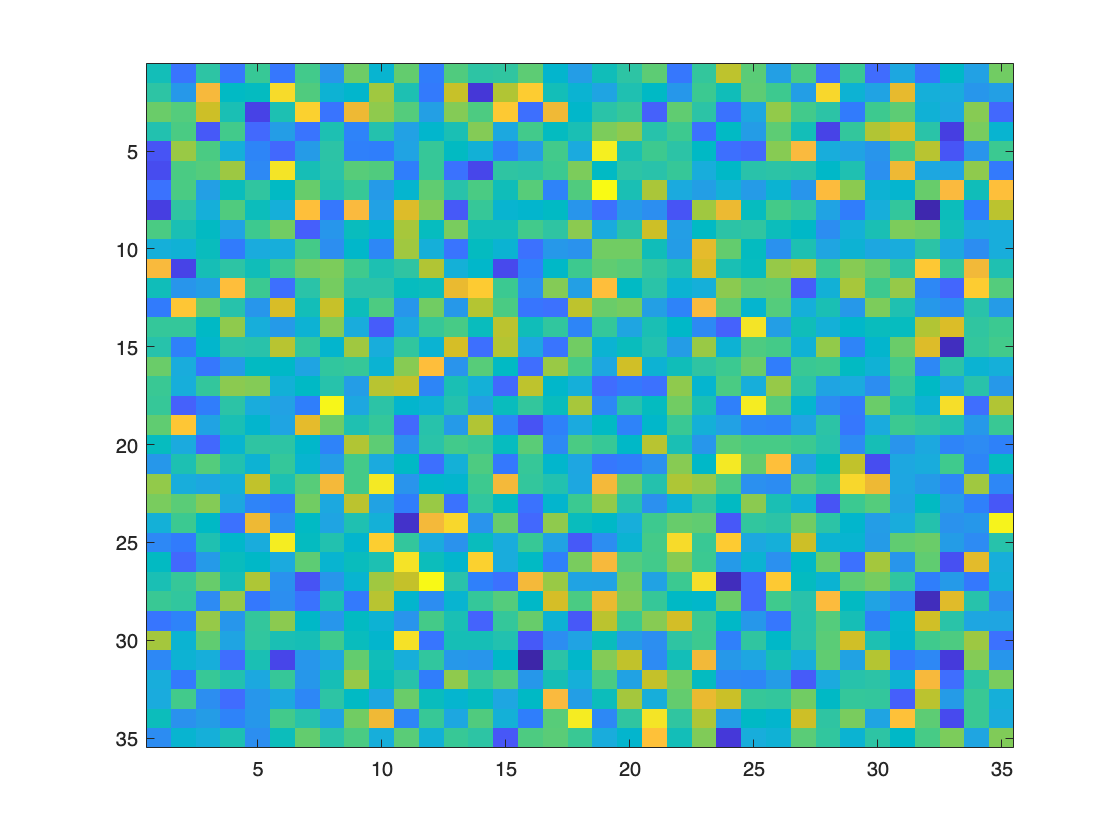

Epoch 5


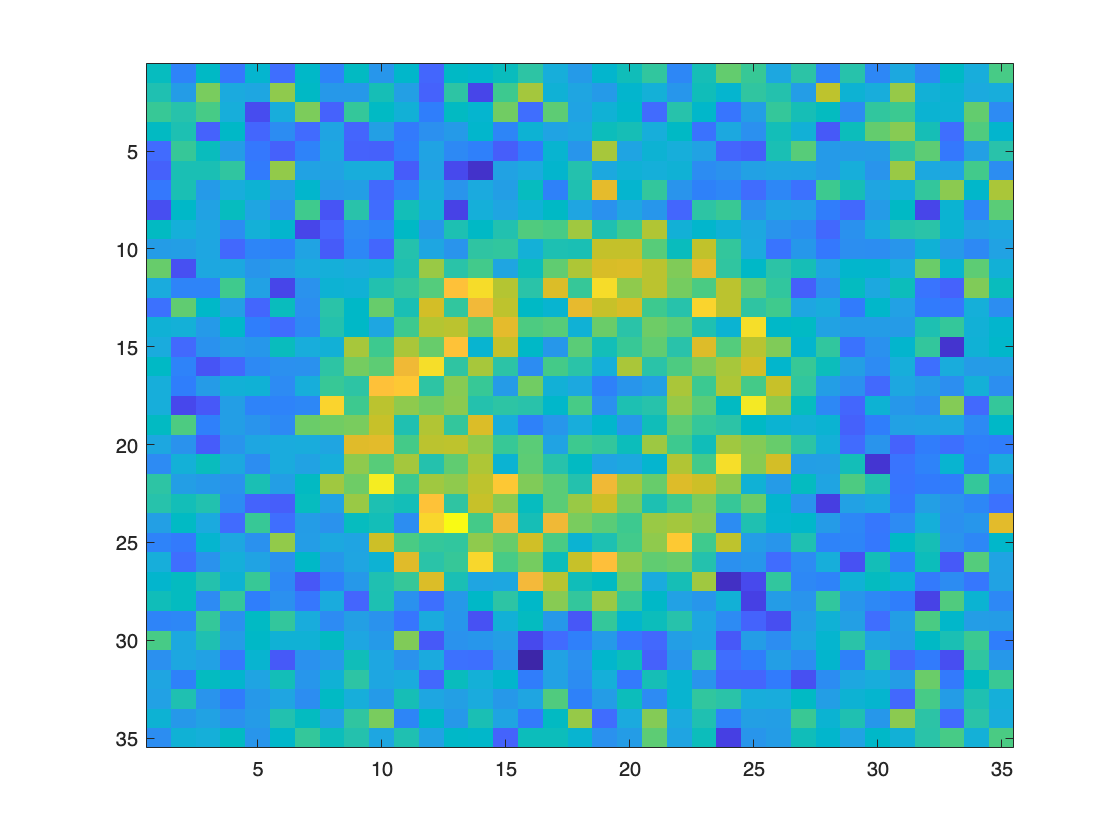

S: 0.1


Epoch: 0


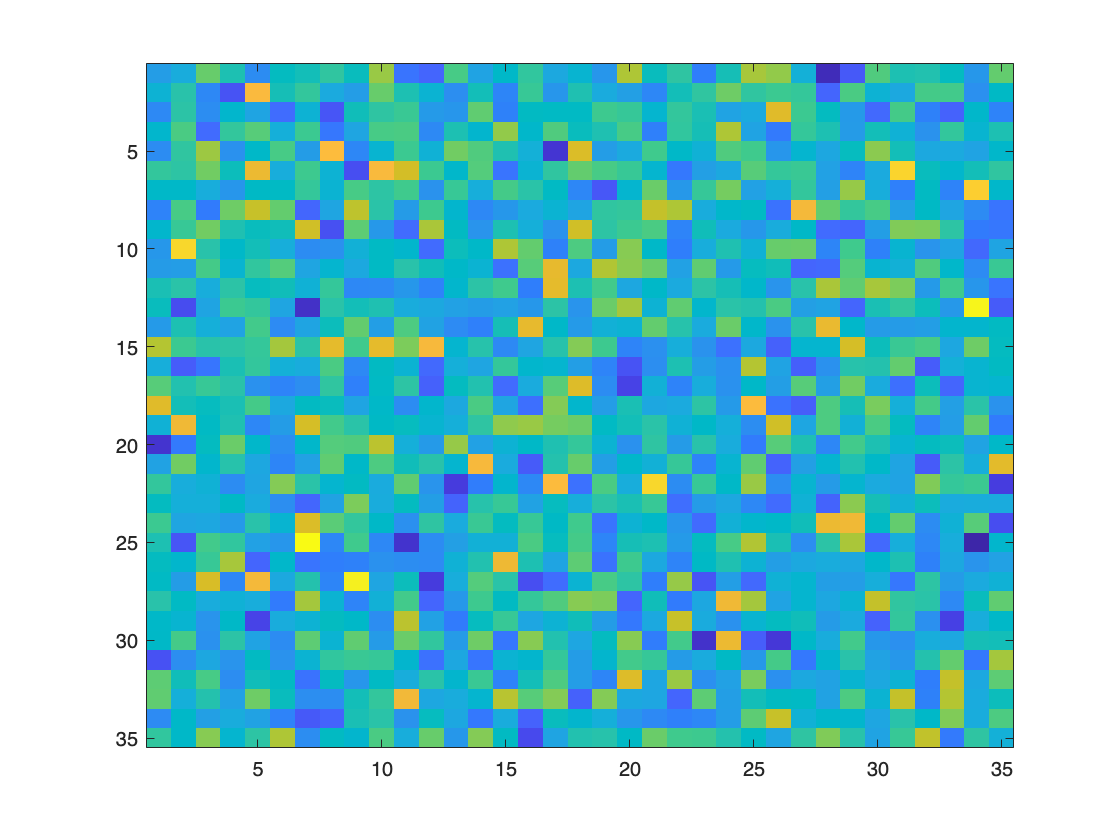

Epoch 5


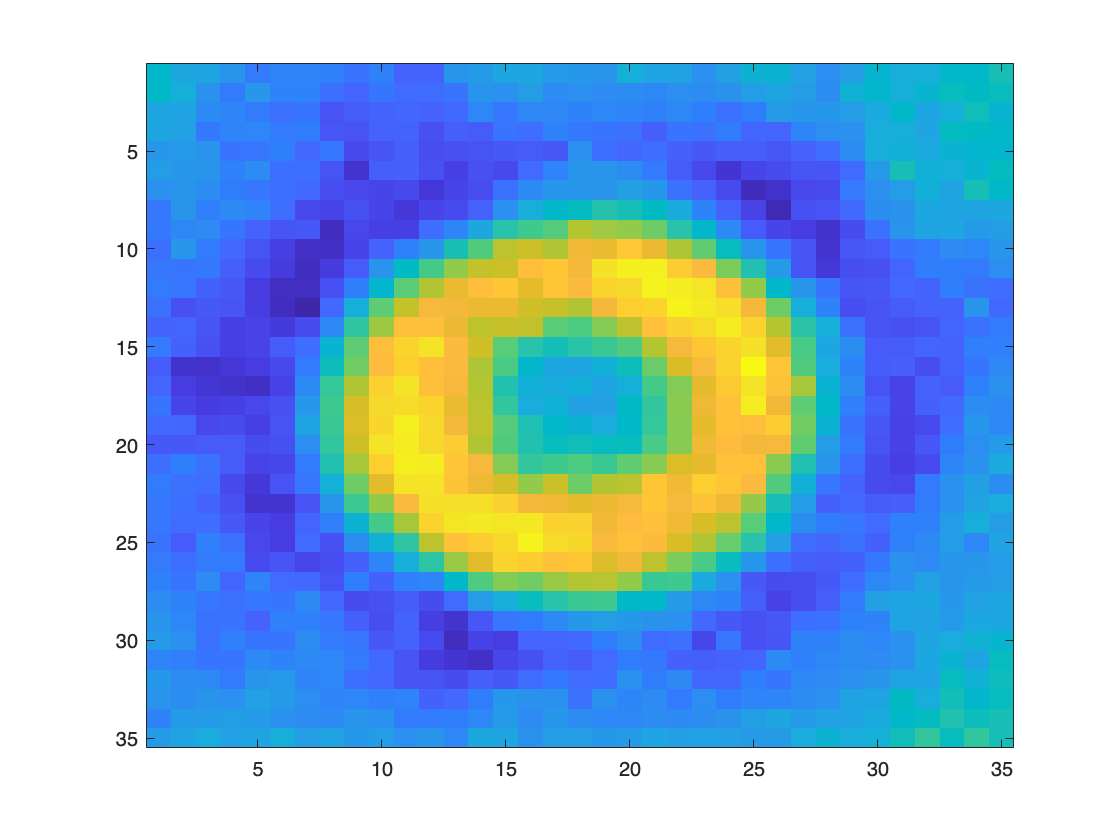

S: 0.01


Epoch: 0


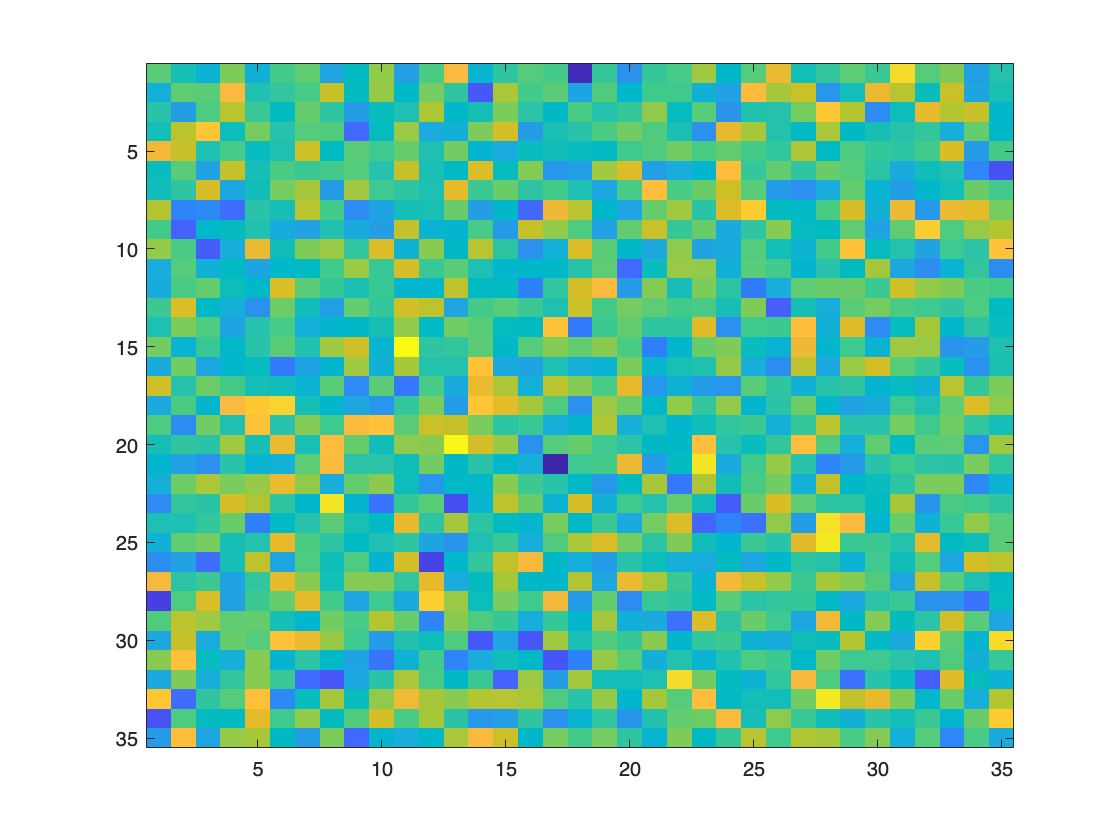

Epoch 5


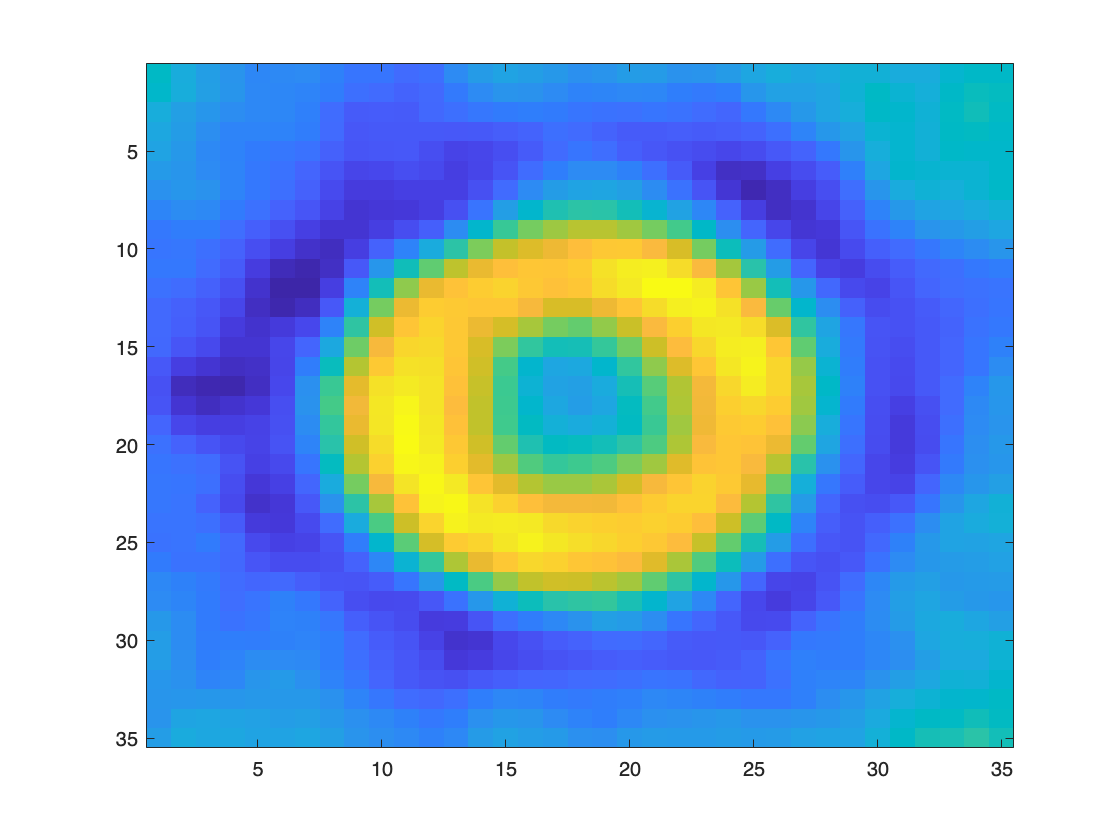

% Your code here
s={10,1,0.1,0.01};
for i=1:length(s)

    w = s{i} * randn(35,35);
    w0 = 0;
    n_epochs = 5;
    lrate = 0.1;
    disp(['S: ', num2str(s{i})])
    disp(['Epoch: 0'])
    figure
    imagesc(w)

    for j=1:n_epochs
    
        [w,w0] = process_epoch(w,w0,lrate,data_train,labels_train);
    
    end
    disp('Epoch 5')
    figure
    imagesc(w)
end

## Ex 2.8 

Make a function

        `predicted_labels = classify(examples_val,w,w0);`

that applies the classifier to the example data. After that, use it on `examples_train` and examples_val and check how much accuracy it gets for each by comparing the predicted labels with `labels_train` and `labels_val` respectively. Write on your report the highest accuracy you were able to achieve in the training and validation data. Hint: train the classifier for longer than 5 epochs to make sure that it converges.

When you have defined the function run the following code.


s = 0.001;
w = s * randn(35,35);
w0 = 0;
n_epochs = 500;
lrate = 0.01;

for i=1:n_epochs

    [w,w0] = process_epoch(w, w0, lrate, data_train, labels_train);

end
predicted_labels = classify(data_val,w,w0);
correct = sum(predicted_labels == labels_val);
accuracy = 100*correct/length(labels_val);
fprintf(["Validation Accuracy: "]+accuracy+["%%"])

Validation Accuracy: 91.25%

**Write the highest accuracy you were able to get here:**

91.25%

## Ex 2.9

The data for training this classifier consists on only 400 examples (less if you consider that you have split it into training and validation). To achieve higher accuracy it might be useful to perform some data augmentation before the training. In this exercise you will increase the number of elements in the training examples by M times. Make a function

        `[examples_train_aug,labels_train_aug] = augment_data(examples_train,labels_train,M)`

that takes each sample of the original training data and applies M random rotations (you can use Matlab function imrotate), from which result M new examples. Store these new examples in examples_train_aug and their corresponding labels in labels_train_aug. Train the classifier with this augmented data and write on your report the new values for accuracy on the training and validation examples.

% Your code here
s = 0.01;
w = s * randn(35,35);
w0 = 0;
n_epochs = 500;
lrate = 0.01;
M = 3;
[examples_train_aug, labels_train_aug] = augment_data(data_train, labels_train, M);

for i=1:n_epochs

    [w,w0] = process_epoch(w, w0, lrate, examples_train_aug, labels_train_aug);

end

predicted_labels = classify(data_val,w,w0);
correct = sum(predicted_labels == labels_val);
accuracy = 100*correct/length(labels_val);
fprintf(["Validation Accuracy: "]+accuracy+["%%"])

Validation Accuracy: 90%

**Write the highest accuracy you were able to get here:**

94.5%

## 2.3 Convolutional neural networks

In the last part, your task is to train convolutional neural networks using Matlab.

## `Ex 2.10 `

Run the following cell

[imgs, labels] = digitTrain4DArrayData;

to load a dataset of images of digits into Matlab. (Make sure you have the Deep Learning toolbox installed). You will find the 5000 digit images in imgs. Plot a few of them to see what the data looks like.

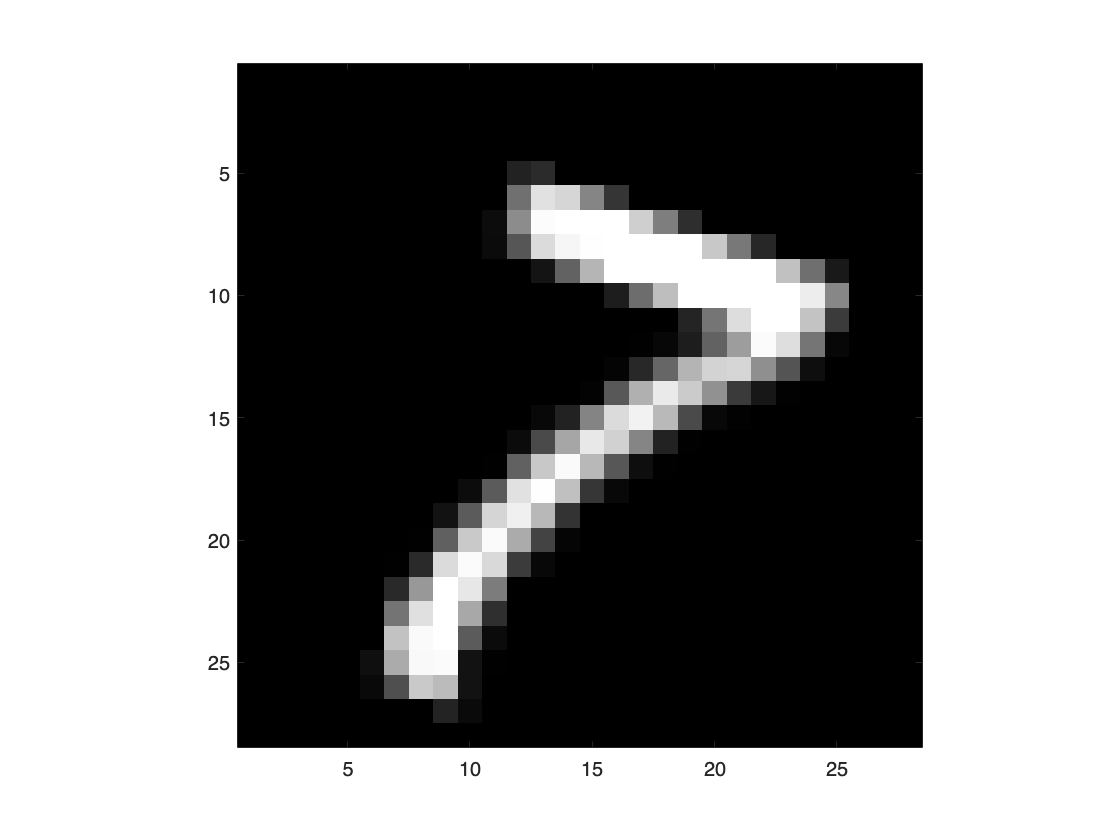

N = 3210; % We have 5000 images so any number between 1 and 5000 works.
img = imgs(:,:,:,N);
imagesc(img), axis image, colormap gray

The next step is to define a network for classification. In Matlab, you do this by simply giving an array of the layers. For example, this would be a linear classifier similar to the one you trained for cells:

        layers = [

            imageInputLayer([35 35 1]);

            fullyConnectedLayer(1);

            softmaxLayer();

            classificationLayer()];

## Ex 2.11 

Make a function

        `layers = basic_cnn_classifier()`

that implements the following network in Matlab:

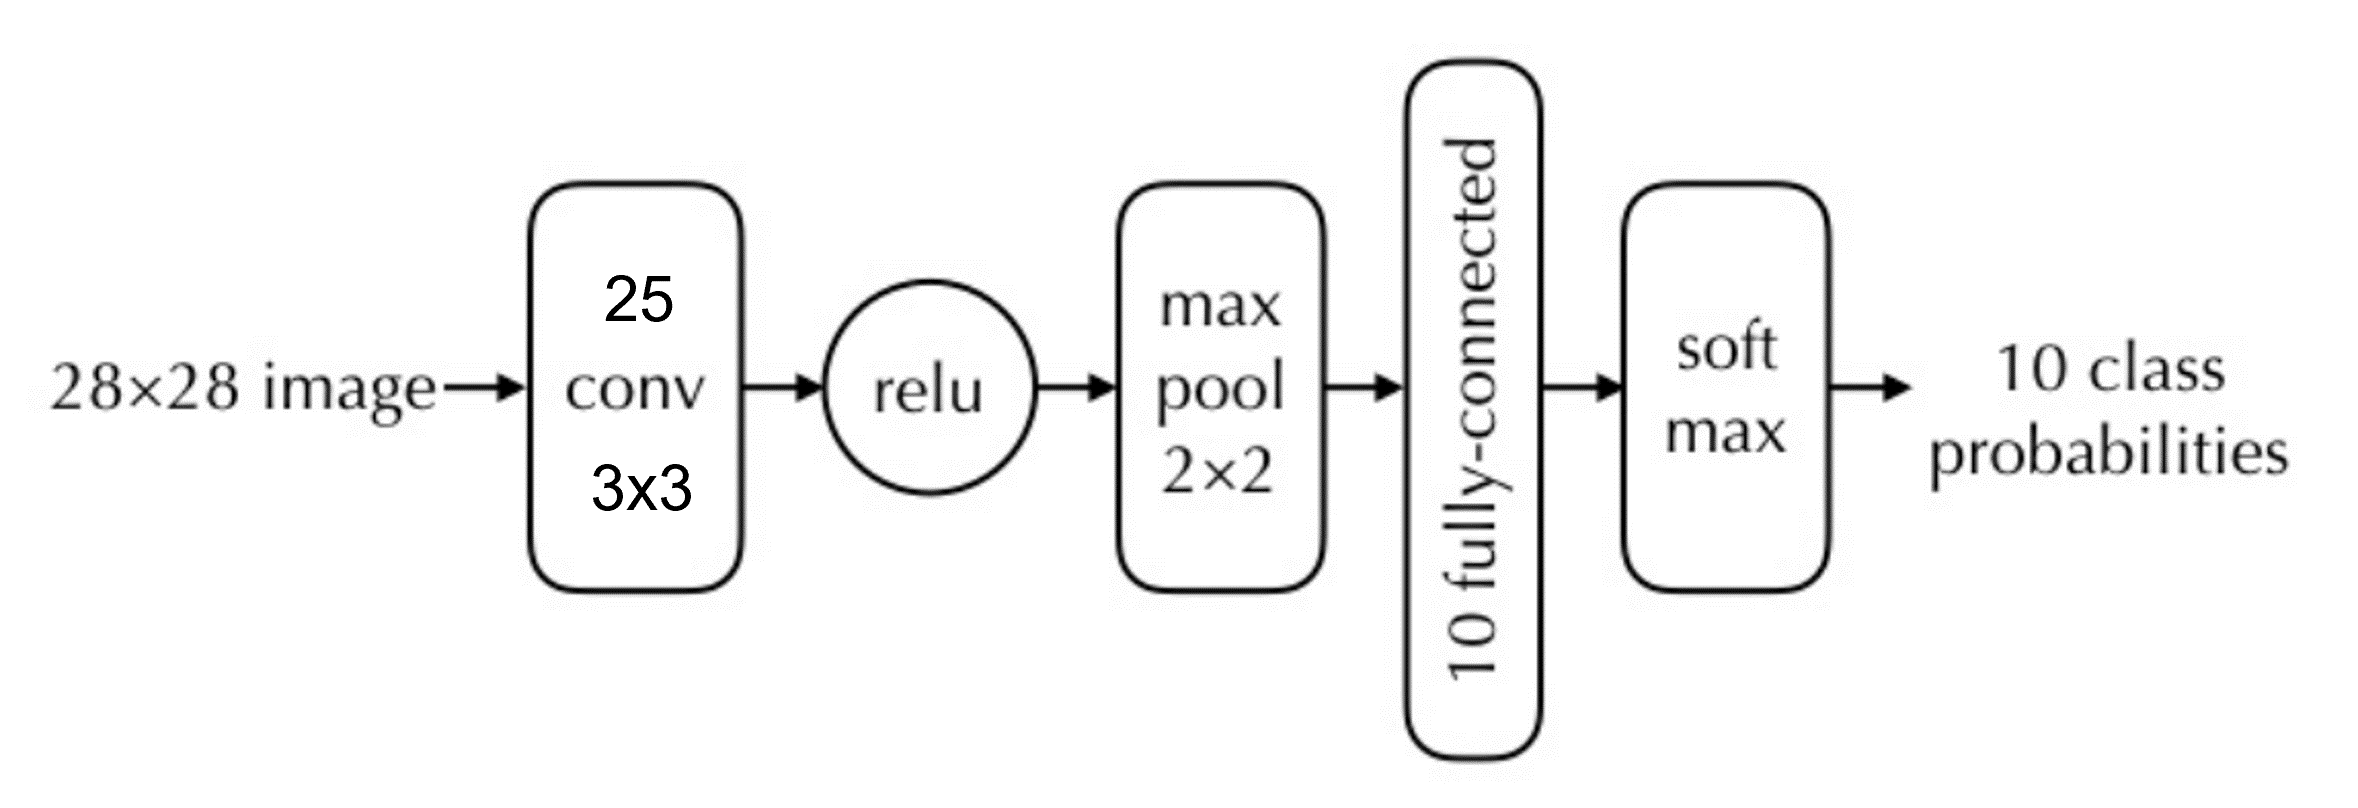

Apart from the layers above the functions `convolution2dLayer`, `reluLayer` and `maxPooling2dLayer` will be useful. Note that you have to set the *stride* for max pooling to 2 to get the expected downsampling.

When you have written the function run the following cell:

layers = basic_cnn_classifier()

layers =   7×1 Layer array with layers:

     1   ''   Image Input             28×28×1 images with 'zerocenter' normalization
     2   ''   2-D Convolution         25 3×3 convolutions with stride [1  1] and padding [0  0  0  0]
     3   ''   ReLU                    ReLU
     4   ''   2-D Max Pooling         2×2 max pooling with stride [2  2] and padding [0  0  0  0]
     5   ''   Fully Connected         10 fully connected layer
     6   ''   Softmax                 softmax
     7   ''   Classification Output   crossentropyex

## Ex 2.12 

Create a set of training options telling Matlab to use stochastic gradient descent with momentum (SGDM), for the optimization:

        `options = trainingOptions('sgdm');`

Now train the network (using default parameters) by running

        net = trainNetwork(imgs, labels, layers, options)

% Your code here
options = trainingOptions('sgdm');
net = trainNetwork(imgs,labels, layers, options);

Training on single CPU.
Initializing input data normalization.
|========================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Mini-batch  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |     Loss     |      Rate       |
|========================================================================================|
|       1 |           1 |       00:00:00 |       13.28% |       2.3081 |          0.0100 |
|       2 |          50 |       00:00:02 |       54.69% |       1.7935 |          0.0100 |
|       3 |         100 |       00:00:04 |       53.12% |       1.4748 |          0.0100 |
|       4 |         150 |       00:00:06 |       66.41% |       1.0719 |          0.0100 |
|       6 |         200 |       00:00:09 |       64.06% |       1.0526 |          0.0100 |
|       7 |         250 |       00:00:11 |       67.19% |       1.0186 |          0.0100 |
|       8 |         300 |  

## Ex 2.13 

Try the network on a few of the training images. You can use `net.predict(img)` to get the ten output probabilities or `net.classify(img)` to get the most probable class.

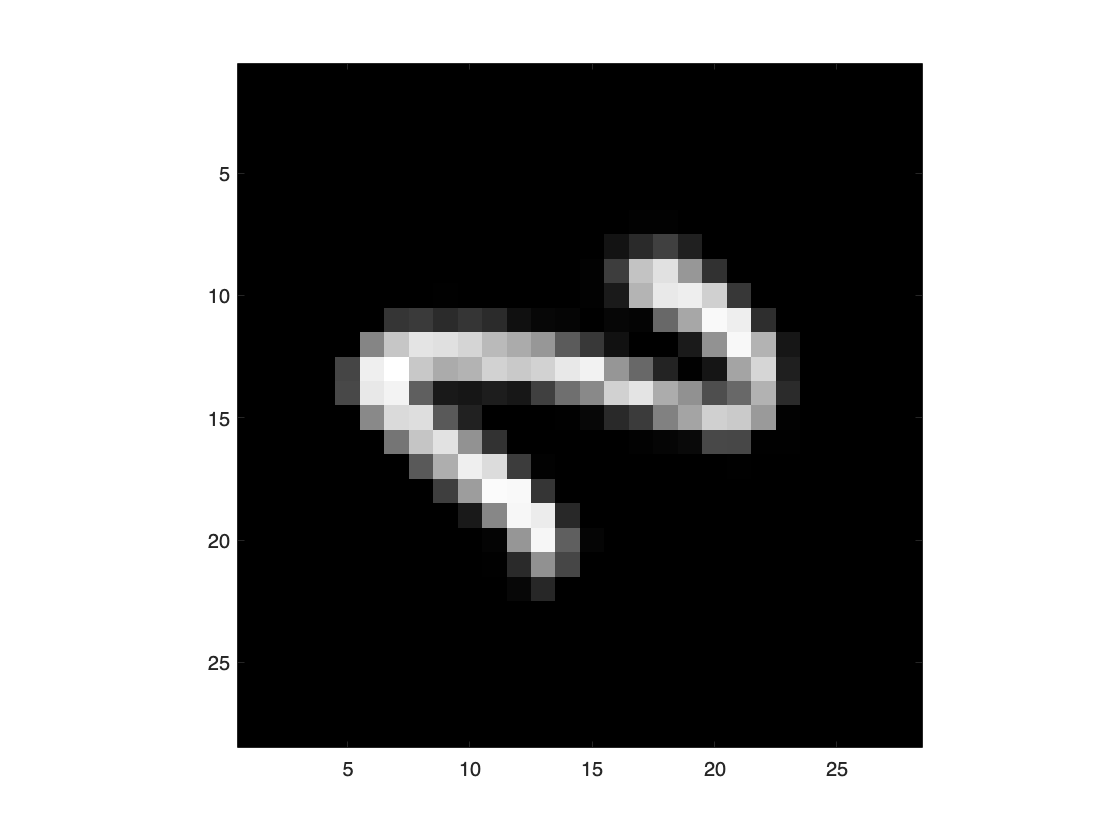

% Your code here
N = randi(5000);
img = imgs(:,:,:,N);
imagesc(img), axis image, colormap gray

net.predict(img)

ans = 1×10 single row vector
    0.0325    0.0000    0.2306    0.0055    0.0451    0.0026    0.0349    0.0004    0.6470    0.0014


net.classify(img)

ans = categorical
     8 


## Ex 2.14 

Work out how many trainable parameters your network contains. Include the answer in your submission. If you explore what the data structure net actually contains, you can find the answer there as well. Note that the convolution layer does not use padding so the output from the convolution layer is smaller than the input.

**Write your answer here:**

The input layer doesn't contain any parameters.

The Convolutional layer, with 1 input channel and 25 output channels, we calculate a total of (3*3+1)*25 = 250 parameters. The output size is (26x26x25).

The MaxPooling layer doesn't introduce any parameters but reduces the input size to (13x13x25).

Next, in the Fully Connected layer, the previous layer's output is flattened to(13*13*25)x1 = (4225x1). With an output shape of (10x1), this layer contains a total of (4225*10)+10 = 42,260 parameters.

Altogether, the model comprises 42,510 parameters.

analyzeNetwork(net.Layers)

## Ex 2.15 

Matlab prints a lot of output, for example the accuracy on the training set. Recall from the lectures that this number is not very good for judging the quality of a classifier. Instead we should save a subset of the data as a validation set, that we can use to evaluate the trained network. 

Divide the data into training `imgs` and `labels` into new variables `imgs_train, labels_train, imgs_val, labels_val`.

% Your code here
percentage_validation = 0.8;
N = length(imgs);

train_size = round(percentage_validation*N);
test_size = N - train_size;

imgs_train = imgs(:,:,:,1:train_size);
labels_train = labels(1:train_size);

imgs_val = imgs(:,:,:,train_size+1:end);
labels_val = labels(train_size+1:end);

Make a function 

        `net = train_classifier(layers, imgs_train, labels_train, imgs_val, labels_val) `

that runs a few epochs of training and then evaluates the accuracy on the validation set. In this case, Matlab has given us a separate test set, so we don’t have to save images for that purpose. *Matlab hints:* You can run multiple images at once by stacking them along the fourth dimension. If you want to continue training the same network you can run

        `net = train_classifier(net.Layers, imgs_train, labels_train, imgs_val, labels_val)`

% Your code here
net = train_classifier(net.Layers, imgs_train, labels_train, imgs_val, labels_val)

Training the network
The network achieved an accuracy of: 98.3%


net =   SeriesNetwork with properties:

         Layers: [7×1 nnet.cnn.layer.Layer]
     InputNames: {'imageinput'}
    OutputNames: {'classoutput'}


**Ex 2.16 **

To run a convolutional neural network we have to perform a massive amount of computations. Hence it is very important to consider the computational load when designing a network. For the network below, compare (roughly) the time consumption of the blue and the red layers. You can ignore effects of padding. Include your answer and your motivation in your submission.

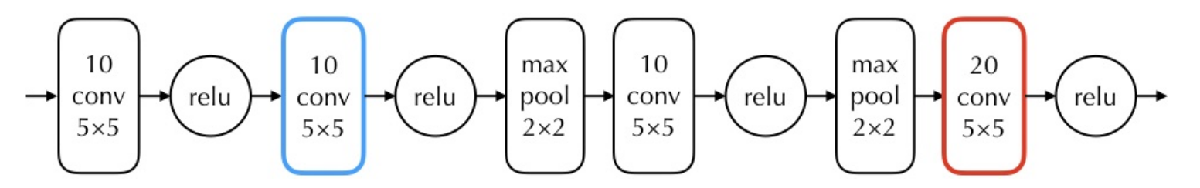

**Write your answer here:**

Considering only the number of multiplications to assess computational complexity:

For the blue convolutional layer with 10 filters of size 5x5, operating on an input of size d * d, approximately (d*d*10)*(5*5*10) = 2500*d*d computations are performed.

For the red convolutional layer with 20 filters of size 5x5, the input size is reduced due to maxpooling, resulting in d/4 * d/4 dimensions. This leads to roughly (d/4*d/4*10)*(5*5*20) = 312.5 d*d computations.

Comparing blue to red, the ratio is 2500/312.5 = 8, indicating that the blue layer requires 8 times more computations than the red layer. Hence, the red convolutional layer performs fewer computations compared to the blue convolutional layer.

## Ex 2.17

Replace the blue box of the network in the figure above by a sequence of two layers of 10 3 × 3 convolutional filters. What changes in terms of network parameters, time consumption and accuracy? Again, you are not supposed to implement the network.

**Write your answer here:**

1x blue conv layer:          (d*d*10) * 1 * (10 * 5 * 5 )  = 2500*d*d

2x blue conv layer:          (d*d*10)*  2 * (10 * 3 * 3 )  = 1800*d*d

The 2x blue conv layer has a significant fewer parameters. It will also have a lower time consumption. Having a small number of parameters may impact the perfromance/accuracy in a negative way. It would reduce the risk of overfitting data, however.

## Ex. 2.18

Make a copy of basic_cnn_classifier.m and name it better_cnn_classifier.m. Try modifying the network by adding more layers. Also experiment with the training options. How much can you improve the results?

We can se by adding 2 convolutional layers we can drastically increase the performance of the network, it needs fewer epochs to improve and rather quickly reaches

% Your code here
layers = better_cnn_classifier()

layers =   11×1 Layer array with layers:

     1   ''   Image Input             28×28×1 images with 'zerocenter' normalization
     2   ''   2-D Convolution         25 3×3 convolutions with stride [1  1] and padding [0  0  0  0]
     3   ''   ReLU                    ReLU
     4   ''   2-D Max Pooling         2×2 max pooling with stride [2  2] and padding [0  0  0  0]
     5   ''   2-D Convolution         20 5×5 convolutions with stride [1  1] and padding [0  0  0  0]
     6   ''   ReLU                    ReLU
     7   ''   2-D Max Pooling         2×2 max pooling with stride [2  2] and padding [0  0  0  0]
     8   ''   Fully Connected         50 fully connected layer
     9   ''   Fully Connected         10 fully connected layer
    10   ''   Softmax                 softmax
    11   ''   Classification Output   crossentropyex

net = train_classifier(layers, imgs_train, labels_train, imgs_val, labels_val)

Training the network
The network achieved an accuracy of: 97.8%


net =   SeriesNetwork with properties:

         Layers: [11×1 nnet.cnn.layer.Layer]
     InputNames: {'imageinput'}
    OutputNames: {'classoutput'}


options = trainingOptions('sgdm', MaxEpochs=13);
net = trainNetwork(imgs,labels, layers, options);

Training on single CPU.
Initializing input data normalization.
|========================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Mini-batch  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |     Loss     |      Rate       |
|========================================================================================|
|       1 |           1 |       00:00:00 |       14.84% |       2.3101 |          0.0100 |
|       2 |          50 |       00:00:02 |       26.56% |       2.1030 |          0.0100 |
|       3 |         100 |       00:00:05 |       58.59% |       1.2603 |          0.0100 |
|       4 |         150 |       00:00:08 |       72.66% |       0.8472 |          0.0100 |
|       6 |         200 |       00:00:11 |       85.16% |       0.4194 |          0.0100 |
|       7 |         250 |       00:00:14 |       96.88% |       0.2534 |          0.0100 |
|       8 |         300 |  

## Ex 2.19 

Load the builtin test images using

        `[imgs_test, labels_test] = digitTest4DArrayData;`

Run the network on all the test images. You apply the network to an image using

        pred = net.classify(image)

Compute precision and recall for each of the 10 classes and include these in your submission. The definitions of precision and recall can be found in the lecture notes chapter 4.

%Your code here
[imgs_test, labels_test] = digitTest4DArrayData;
preds = net.classify(imgs_test);

for c=0:9

    class = num2str(c);
    idx = find(labels_test==class);
    tp = nnz(preds(idx)==class);
    precision = tp/nnz(preds==class);
    recall = tp/length(idx);

    disp(class)
    disp(['Precision: ',num2str(precision)])
    disp(['Recall: ', num2str(recall)])

end

0


Precision: 0.992


Recall: 0.992


1


Precision: 0.97024


Recall: 0.978


2


Precision: 0.97996


Recall: 0.978


3


Precision: 0.97769


Recall: 0.964


4


Precision: 0.94677


Recall: 0.996


5


Precision: 0.99189


Recall: 0.978


6


Precision: 0.99789


Recall: 0.944


7


Precision: 1


Recall: 0.978


8


Precision: 0.97211


Recall: 0.976


9


Precision: 0.94434


Recall: 0.984


## Ex 2.20

Save three of the failure cases with names indicating what digit they were mistaken for. Include these in your submission. You can use imwrite(img, ’mistaken_as_5.png’) to save an image if it is correctly scaled. Have a look at the file before submitting it, so it looks right.

You can load and display the images here using imagesc:

     Real label:      9 



     Predicted label:      4 



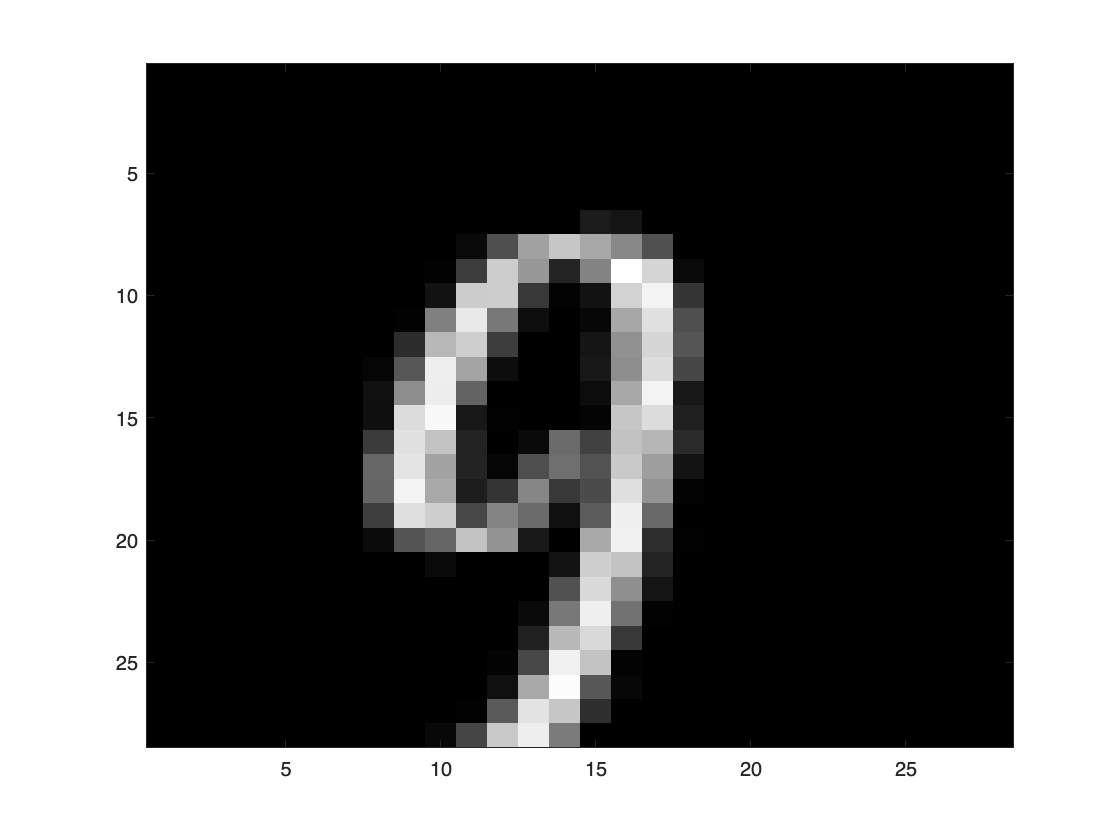

     Real label:      5 



     Predicted label:      9 



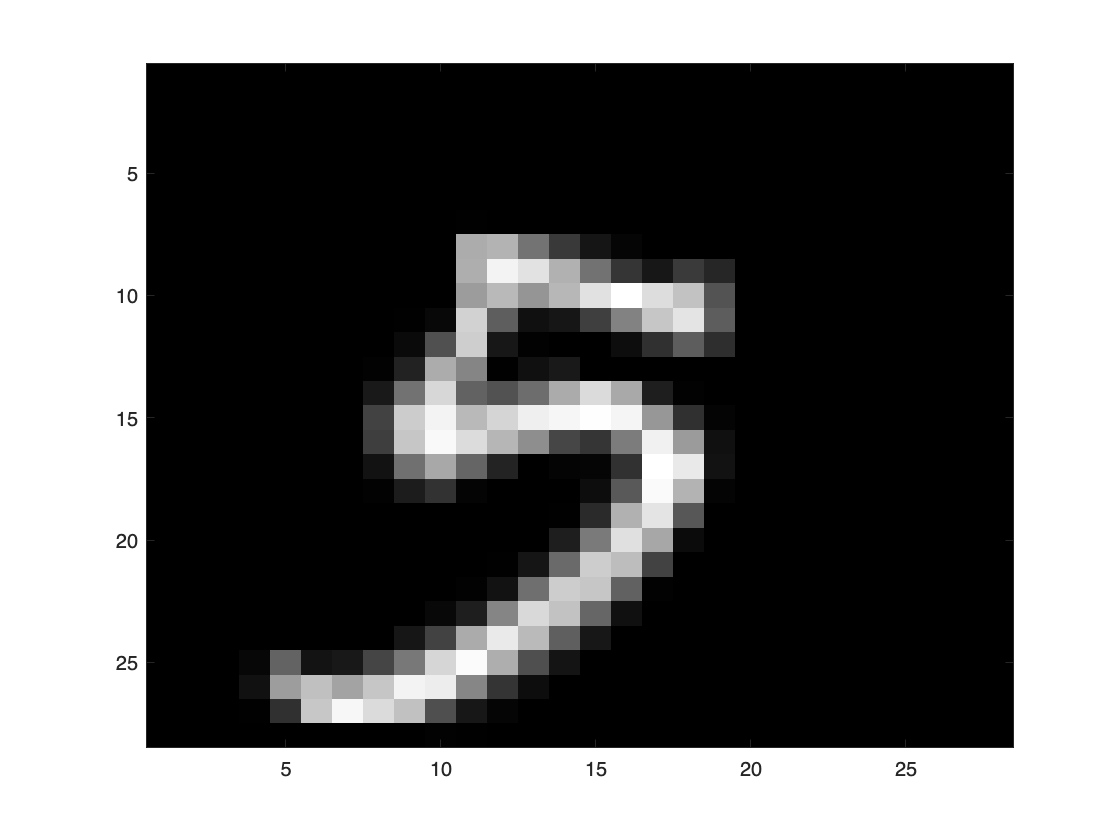

     Real label:      0 



     Predicted label:      9 



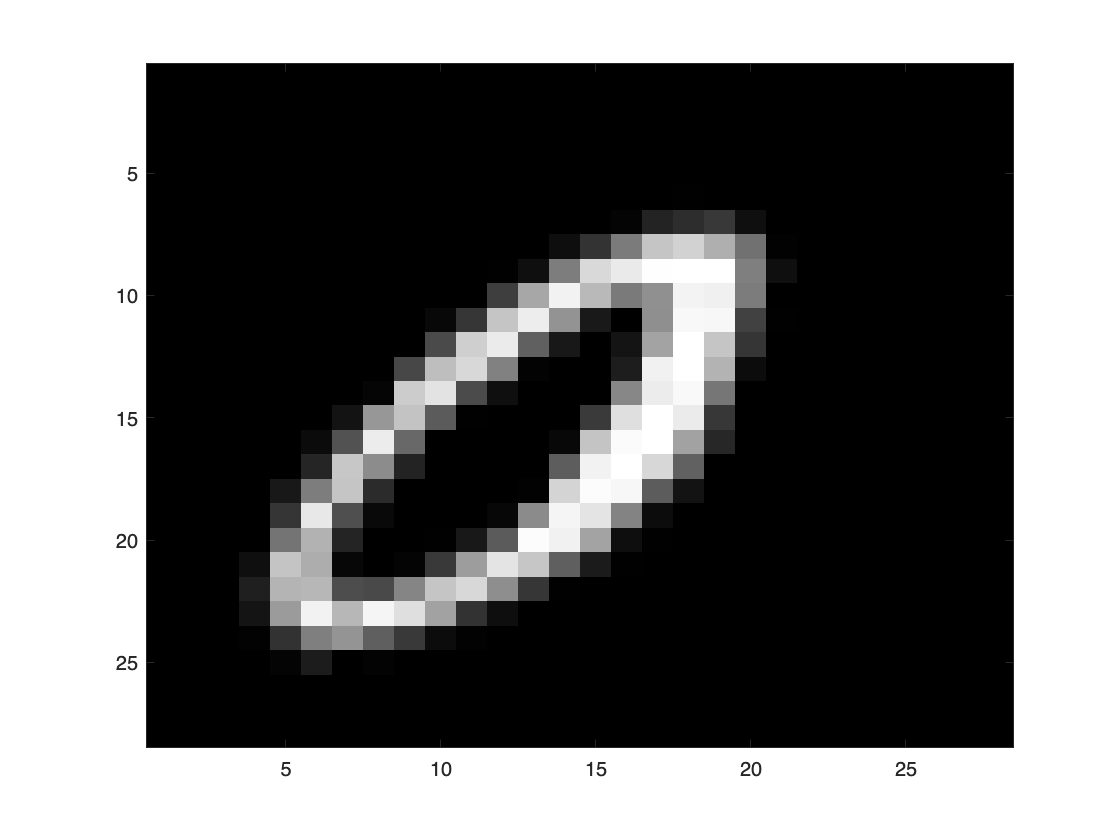

% Your code here
n_fails = 3;
fail = find(preds ~= labels_test);
idx = randperm(length(fail),n_fails);
fail_idx = fail(idx);
for i=1:n_fails
    
    real_label = labels_test(fail_idx(i));
    predicted_label = preds(fail_idx(i));
    img = imgs_test(:,:,:,fail_idx(i));

    disp(['Real label: ' real_label])
    disp(['Predicted label: ' predicted_label])
    figure,imagesc(img),colormap gray
    img_name = strcat('/Users/meng_fanze/Library/CloudStorage/OneDrive-Chalmers/Master 1/SSY098 Image Analysis/Lab2/lab2_group35/data',string(real_label), '_mistaken_as_', string(predicted_label),'.png');
    imwrite(img, img_name);

end